# CAPÍTULO 15 - BARRAS DE GRAN CURVATURA

Calcula el eje neutro y las tensiones de una sección curva, o la respuesta de un arco circular en voladizo.

Dimensión: arco circular en un plano que puede orientarse en el espacio. Las fuerzas deben pertenecer a ese plano. Una fuerza fuera de él necesita un modelo de flexión/torsión espacial diferente.

Modifica los datos y pulsa Run. Las funciones de cálculo están en esta misma carpeta. Abre INICIAR_CURSO.m y ejecútalo una vez al iniciar MATLAB.

## 1. Datos / Input data

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto.

assert(exist('rm_lineal','file')==2, 'Ejecuta INICIAR_CURSO.m una vez antes de abrir los capitulos.');

modo="arco" o "seccion". radios y anchuras describen el material en dirección radial. En arco, anguloArco se mide desde la tangente inicial; fuerza tiene componentes [Fx Fy]. direccionConsulta define el desplazamiento a calcular. En sección se usan Nseccion y Mseccion.

modo="arco";
radios=[.08 .12]; anchuras=[.03 .03];
E=210e9; nu=.3;
anguloArco=pi/2; fuerza=[0 -1000]; direccionConsulta=[0 -1];
Nseccion=1000; Mseccion=200;
origenArco=[0 0 0];direccionXArco=[1 0 0];normalPlanoArco=[0 1 1];
incluirCortante=false; factorCortante=1.2;

## 2. Centroide y eje neutro


$$F=\int b(r)dr,\quad R=\frac{\int r b(r)dr}{F},\quad r_n=\frac{F}{\int b(r)/r\,dr},\quad e=R-r_n$$



$$\sigma(r)=\frac{N}{F}+\frac{M}{Fe}\left(1-\frac{r_n}{r}\right)$$


r se mide desde el centro de curvatura. M positivo produce tracción en las fibras exteriores. El eje neutro no coincide con el centroide; por eso la distribución es hiperbólica. El área y el momento se integran con las anchuras suministradas.

assert(all(radios>0) && all(diff(radios)>0) && all(anchuras>=0) && E>0 && nu>-1 && nu<.5,'Seccion invalida.');
b=@(r) interp1(radios,anchuras,r,'linear');
F=integral(b,min(radios),max(radios),'Waypoints',radios(2:end-1));
assert(F>0,'Area nula.');
R=integral(@(r) r.*b(r),min(radios),max(radios),'Waypoints',radios(2:end-1))/F;
rn=F/integral(@(r) b(r)./r,min(radios),max(radios),'Waypoints',radios(2:end-1));
e=R-rn; assert(e>0,'Curvatura no resoluble con estos datos.');
rr=linspace(min(radios),max(radios),1001)';
if modo=="seccion"
    N=Nseccion; M=Mseccion;
    sigma=N/F+M/(F*e)*(1-rn./rr);
    resultado=struct('F',F,'R',R,'rn',rn,'e',e,'sigma',sigma);
else
    assert(modo=="arco" && anguloArco>0 && anguloArco<=pi && norm(direccionConsulta)>0 ...
        && numel(fuerza)==2 && numel(direccionConsulta)==2,'Usa fuerza y consulta con dos componentes en el plano local.');
    th=linspace(0,anguloArco,1001)'; ss=R*th;
    xx=R*sin(th); yy=R*(1-cos(th));
    N=fuerza(1)*cos(th)+fuerza(2)*sin(th);
    Q=fuerza(1)*sin(th)-fuerza(2)*cos(th);
    M=(xx(end)-xx)*fuerza(2)-(yy(end)-yy)*fuerza(1);
    unit=direccionConsulta/norm(direccionConsulta);
    n=unit(1)*cos(th)+unit(2)*sin(th); q=unit(1)*sin(th)-unit(2)*cos(th);
    m=(xx(end)-xx)*unit(2)-(yy(end)-yy)*unit(1);
    integrando=M.*m/(E*F*e*R)+N.*n/(E*F)+(M.*n+N.*m)/(E*F*R);
    energia=M.^2/(2*E*F*e*R)+N.^2/(2*E*F)+M.*N/(E*F*R);
    if incluirCortante
        G=E/(2*(1+nu)); integrando=integrando+factorCortante*Q.*q/(G*F);
        energia=energia+factorCortante*Q.^2/(2*G*F);
    end
    desplazamiento=trapz(ss,integrando); U=trapz(ss,energia);
    sigmaInterior=N/F+M/(F*e)*(1-rn/min(radios));
    sigmaExterior=N/F+M/(F*e)*(1-rn/max(radios));
    [~,critico]=max(max(abs([sigmaInterior sigmaExterior]),[],2));
    sigma=N(critico)/F+M(critico)/(F*e)*(1-rn./rr);
    resultado=struct('F',F,'R',R,'rn',rn,'e',e,'delta',desplazamiento,'energia',U, ...
        'sigmaInterior',sigmaInterior,'sigmaExterior',sigmaExterior);
    disp("Desplazamiento en la direccion indicada [mm]: "+1000*desplazamiento);
end

Desplazamiento en la direccion indicada [mm]: 0.010969


disp(table(F,R,rn,e));

      F        R        rn           e    
    ______    ___    ________    _________

    0.0012    0.1    0.098652    0.0013479



## 3. Energía y representación


$$\Delta=\int\left[\frac{Mm}{EF eR}+\frac{Nn}{EF}+\frac{Mn+Nm}{EFR}+k_Q\frac{Qq}{GF}\right]ds$$


El término de cortante es opcional. Los términos cruzados entre N y M son propios de esta teoría curva. Las tensiones extremas de una sección se encuentran en los radios extremos.

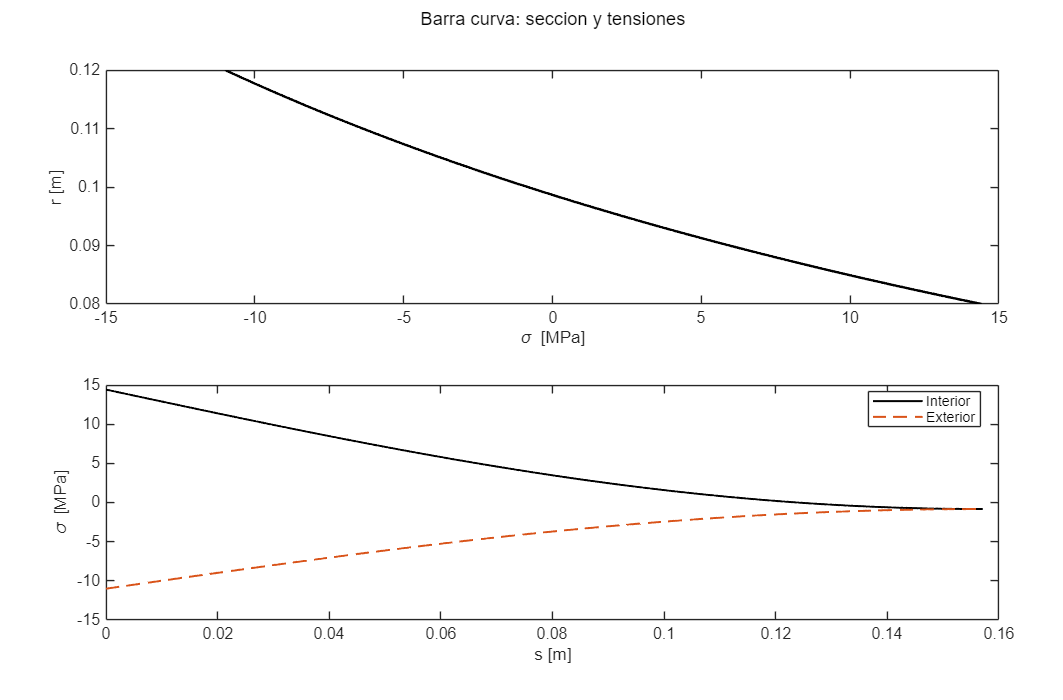

[figura,ejes]=rm_figura(2,'Barra curva: seccion y tensiones');
plot(ejes(1),sigma/1e6,rr,'k-','LineWidth',1.5); xlabel(ejes(1),'\sigma [MPa]'); ylabel(ejes(1),'r [m]');
if modo=="arco"
    plot(ejes(2),ss,sigmaInterior/1e6,'k-',ss,sigmaExterior/1e6,'--','LineWidth',1.2);
    legend(ejes(2),{'Interior','Exterior'},'Location','best'); xlabel(ejes(2),'s [m]'); ylabel(ejes(2),'\sigma [MPa]');
else
    rm_curva(ejes(2),rr,1-rn./rr,'Factor 1-r_n/r',false); xlabel(ejes(2),'r [m]');
end

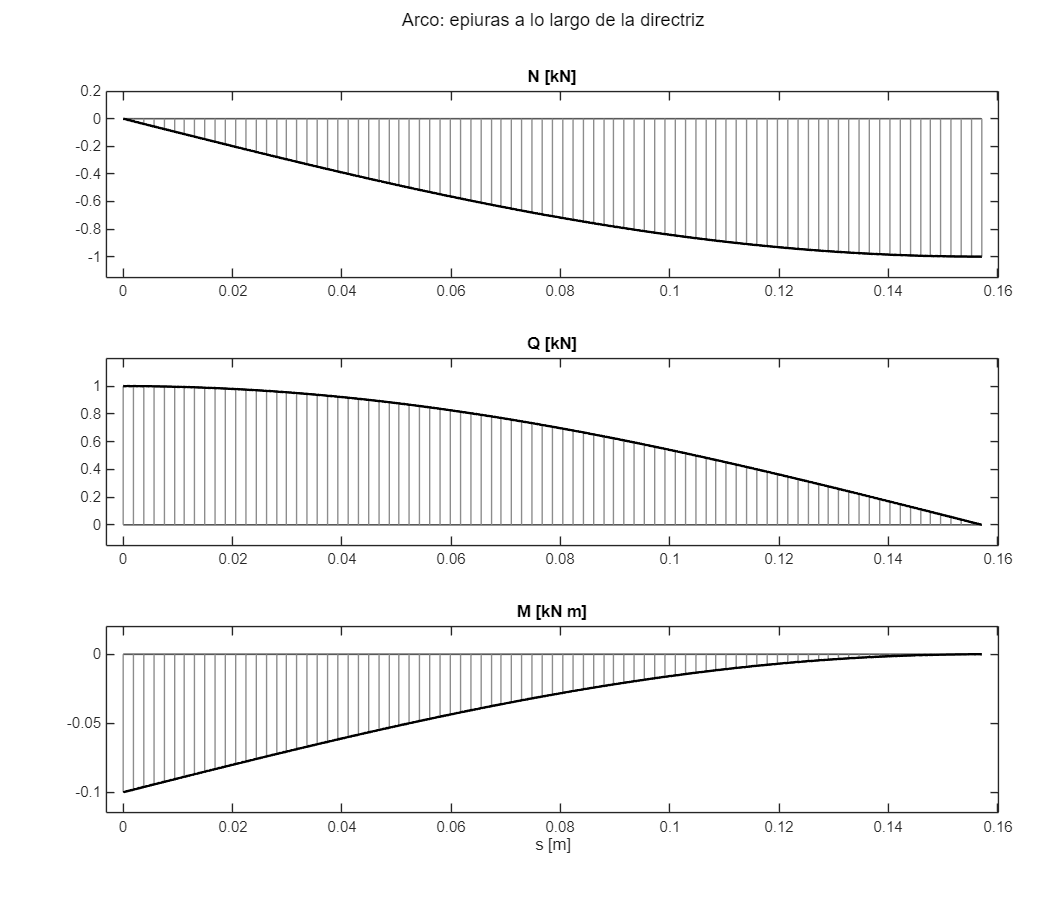

if modo=="arco"
    [figura,ejes]=rm_figura(3,'Arco: epiuras a lo largo de la directriz');
    rm_curva(ejes(1),ss,N/1000,'N [kN]');
    rm_curva(ejes(2),ss,Q/1000,'Q [kN]');
    rm_curva(ejes(3),ss,M/1000,'M [kN m]'); xlabel(ejes(3),'s [m]');
end

direccionXArco y normalPlanoArco orientan el dibujo en el espacio. fuerza y direccionConsulta conservan sus dos componentes locales en el plano del arco. Esta orientación no añade capacidad para cargas fuera del plano.

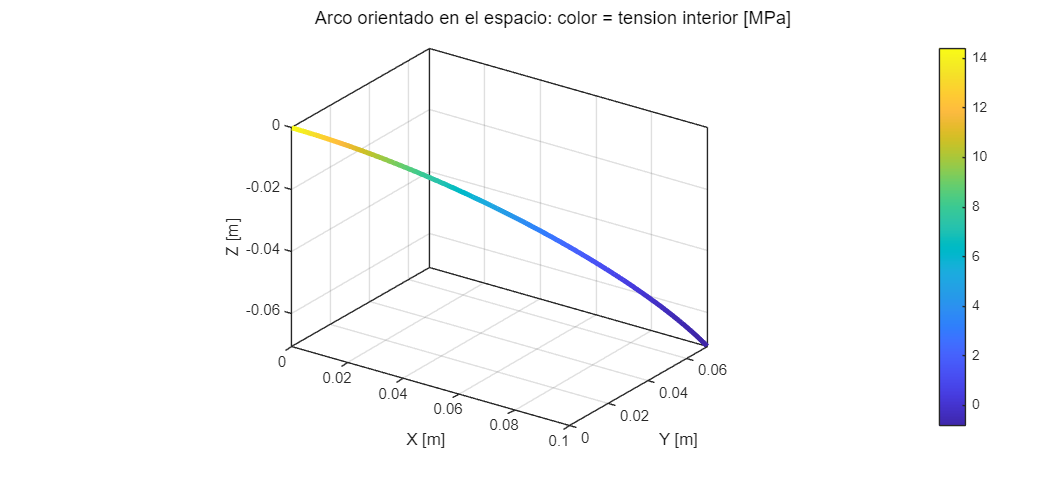

if modo=="arco"
    ex=direccionXArco/norm(direccionXArco);normal=normalPlanoArco/norm(normalPlanoArco);
    assert(abs(dot(ex,normal))<1e-8,'La direccion X debe ser perpendicular a la normal del plano.');
    ey=cross(normal,ex);
    puntos=origenArco+xx*ex+yy*ey;
    [figura,ejes]=rm_figura(1,'Arco orientado en el espacio: color = tension interior [MPa]');
    surface(ejes(1),[puntos(:,1)';puntos(:,1)'],[puntos(:,2)';puntos(:,2)'], ...
        [puntos(:,3)';puntos(:,3)'],[sigmaInterior';sigmaInterior']/1e6, ...
        'FaceColor','none','EdgeColor','interp','LineWidth',3);
    view(ejes(1),35,24);axis(ejes(1),'equal');grid(ejes(1),'on');colorbar(ejes(1));
    xlabel(ejes(1),'X [m]');ylabel(ejes(1),'Y [m]');zlabel(ejes(1),'Z [m]');
end

## Funciones utilizadas

integral: realiza integración numérica adaptativa. Aquí obtiene área, centroide y radio neutro con los cambios de anchura.

interp1: interpola una tabla. Aquí define la anchura entre los radios introducidos.

trapz: integra valores muestreados. Aquí evalúa el trabajo virtual a lo largo del arco.

disp muestra valores; aquí presenta las tablas y conclusiones. assert comprueba una condición; aquí rechaza datos incompatibles. table reúne columnas con nombre; aquí permite leer resultados con unidades. rm_figura prepara ejes verticales; aquí reserva espacio para títulos y unidades. rm_curva dibuja una magnitud; aquí diferencia el cero gris de la curva negra y el rayado.

GUIA_MATLAB.md, en esta misma carpeta, explica las operaciones básicas en general y con un ejemplo de su uso en estos capítulos.

## Alcance y conexiones

Barras curvas de sección constante y material elástico lineal. La sección se describe mediante anchura frente a radio. El arco es circular y está empotrado en un extremo, con fuerza en el otro. No incluye alabeo, torsión espacial ni redistribución plástica.

Conexión con lo anterior: Combina esfuerzo axial del capítulo 1, propiedades de sección del capítulo 3 y trabajo virtual del capítulo 7. La distribución de tensión sustituye la ley lineal de vigas rectas.

Cambiar datos no requiere editar las ecuaciones. Una geometría, ley de material o condición fuera del alcance indicado requiere ampliar el modelo. Un cálculo que satisface equilibrio no demuestra por sí solo resistencia o estabilidad suficiente.

disp('Capitulo 15: calculo completado.');

Capitulo 15: calculo completado.
